# Two-step FAVAR

Tutorial file for testing two-step FAVAR estimators

## Housekeeping

clear
close all
clear classes

rehash path


  
import factorTwostep.*


## Convenience functions

The `extremesFunc` function compresses any number of samples (draws from the posterior) into two numbers - the minimum and the maximum.

percentiles = [10, 50, 90];

prctileFunc = @(x) prctile(x, percentiles, 2);

extremesFunc = @(x) [min(x, [], 2), max(x, [], 2)];

numPresampled = 100;

## Prepare data and a reduced-form model

Note that the meta information is common to all two-factor FAVAR models, regardless of the specific estimator used.

The properties specific to the two-step FAVAR are as follows:

**reducibleNames** – variables used for constructing the factors. 

**reducibleBlocks** – names of the blocks, indicating which block each reducible belongs to. Note that even if you have only one block, it must still be specified.Note that if you select the `"slowfast"` method in `blockType`, the group names must be `"slow"` and `"fast"`.

**blockType** – specifies which type of estimation method to use. Possible values are:

- `"blocks"` – default value, also used when there is only one block,

- `"slowfast"` – used for the slow–fast method.

**numFactors** – defines how many factors to use for a given block.

inputTbx = tablex.fromFile("FAVAR.csv");

estimStart = datex.m(1960,3);
estimEnd = datex.m(2001,8);
estimSpan = datex.span(estimStart, estimEnd);

meta = Meta( ...
    endogenousNames=["FYFF"],...
    exogenous=[],...
    order=13, ...
    intercept=false, ...
    estimationSpan=estimSpan, ...
    reducibleNames=["IPP" , "IPF" , "IPC" , "IPCD" , "IPCN" , "IPE" , "IPI" , "IPM" , "IPMD" , "IPMND" ,...
        "IPMFG" , "IPD" , "IPN" , "IPMIN" , "IPUT" , "IP" , "IPXMCA" , "PMI" , "PMP" , "GMPYQ" , "GMYXPQ" , ...
        "LHEL" , "LHELX" , "LHEM" , "LHNAG" , "LHUR" , "LHU680" , "LHU5" , "LHU14" , "LHU15" , "LHU26" ,...
        "LPNAG" , "LP" , "LPGD" , "LPMI" , "LPCC" , "LPEM" , "LPED" , "LPEN" , "LPSP" , "LPTU" , "LPT" ,...
        "LPFR" , "LPS" , "LPGOV" , "LPHRM" , "LPMOSA" , "PMEMP" , "GMCQ" , "GMCDQ" , "GMCNQ" , "GMCSQ" ,...
        "GMCANQ" , "HSFR" , "HSNE" , "HSMW" , "HSSOU" , "HSWST" , "HSBR" , "HMOB" , "PMNV" , "PMNO" , ...
        "PMDEL" , "MOCMQ" , "MSONDQ" , "FSNCOM" , "FSPCOM" , "FSPIN" , "FSPCAP" , "FSPUT" , "FSDXP" , ...
        "FSPXE" , "EXRSW" , "EXRJAN" , "EXRUK" , "EXRCAN" , "FYGM3" , "FYGM6" , "FYGT1" , "FYGT5" , ...
        "FYGT10" , "FYAAAC" , "FYBAAC" , "SFYGM3" , "SFYGM6" , "SFYGT1" , "SFYGT5" , "SFYGT10" , ...
        "SFYAAAC" , "SFYBAAC" , "FM1" , "FM2" , "FM3" , "FM2DQ" , "FMFBA" , "FMRRA" , "FMRNBA" , ...
        "FCLNQ" , "FCLBMC" , "CCINRV" , "PMCP" , "PWFSA" , "PWFCSA" , "PWIMSA" , "PWCMSA" , "PSM99Q" , ...
        "PUNEW" , "PU83" , "PU84" , "PU85" , "PUC" , "PUCD" , "PUS" , "PUXF" , "PUXHS" , "PUXM" , "LEHCC" , "LEHM" , "HHSNTN"], ...
    reducibleBlocks=["main", "main", "main", "main", "main", "main", "main", "main", ...
        "main", "main", "main", "main", "main", "main", "main", "main", "main", "main", ...
        "main", "main", "main", "main", "main", "main", "main", "main", "main", "main", ...
        "main", "main", "main", "main", "main", "main", "main", "main", "main", "main", ...
        "main", "main", "main", "main", "main", "main", "main", "main", "main", "main", ...
        "main", "main", "main", "main", "main", "main", "main", "main", "main", "main", ...
        "main", "main", "main", "main", "main", "main", "main", "main", "main", "main", ...
        "main", "main", "main", "main", "main", "main", "main", "main", "main", "main", ...
        "main", "main", "main", "main", "main", "main", "main", "main", "main", "main", ...
        "main", "main", "main", "main", "main", "main", "main", "main", "main", "main", ...
        "main", "main", "main", "main", "main", "main", "main", "main", "main", "main", ...
        "main", "main", "main", "main", "main", "main", "main", "main", "main", "main", "main"],...
    blockType = "blocks", ...    
    numFactors = struct("main",2), ...
    identificationHorizon=12);
dataH = DataHolder(meta, inputTbx);


## Reduced form models

The estimator-specific settings are always the same as those for the corresponding plain BVARs.

### Basic FAVARs

#### **Minnesota priors**

**Sigma** – controls the priors used for calculating the covariance matrix. Possible values are:

- **ar** – uses the variances matrix from estimated AR models foer each variable (with the same order as the final model),

- **diag** – uses only the diagonal elements of the covariance matrix from an estimated VAR (with the same order as the final model),

- **full** – uses the full covariance matrix from an estimated VAR (with the same order as the final model).

estimatorR1 = estimator.MinnesotaFAVARTwostep()

estimatorR1 =   MinnesotaFAVARTwostep with properties:

                Settings: [1×1 factorTwostep.estimator.settings.MinnesotaFAVARTwostep]
             Description: "Two-step FAVAR with Minnesota prior"
                Category: "Plain FAVAR estimators"
           HasCrossUnits: 0
         CanBeIdentified: 1
          OneStepFactors: 0
                   FAVAR: []
          CanHaveDummies: 0
                 Sampler: []
           SampleCounter: 0
           HistoryDrawer: []
     UnconditionalDrawer: []
       ConditionalDrawer: []
    IdentificationDrawer: []
          ShortClassName: 'MinnesotaFAVARTwostep'
         BeenInitialized: 0


modelR1 = ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR1 ...
);


#### **Normal Wishart priors**

**Sigma** – controls the priors used for calculating the covariance matrix. Possible values are:

- **ar** – uses the variances matrix from estimated AR models foer each variable (with the same order as the final model),

- **eye** – using the identity matrx


% estimatorR1 = estimator.NormalWishartFAVARTwostep()
% modelR1 = ReducedForm( ...
%     meta=meta ...
%     , dataHolder=dataH ...
%     , estimator=estimatorR1 ...
% );


#### **Normal Diffuse priors**

There are no estimator-specific settings other than the hyperparameters.


% estimatorR1 = estimator.NormalDiffuseFAVARTwostep()
% modelR1 = ReducedForm( ...
%     meta=meta ...
%     , dataHolder=dataH ...
%     , estimator=estimatorR1 ...
% );


#### **Individual Normal Wishart priors**

**Sigma** – controls the priors used for calculating the covariance matrix. Possible values are:

- **ar** – uses the variances matrix from estimated AR models foer each variable (with the same order as the final model),

- **eye** – using the identity matrx


% estimatorR1 = estimator.IndNormalWishartFAVARTwostep()
% modelR1 = ReducedForm( ...
%     meta=meta ...
%     , dataHolder=dataH ...
%     , estimator=estimatorR1 ...
% );


#### **Flat priors**

There are no estimator-specific settings other than the hyperparameters.


% estimatorR1 = estimator.FlatFAVARTwostep()
% modelR1 = ReducedForm( ...
%     meta=meta ...
%     , dataHolder=dataH ...
%     , estimator=estimatorR1 ...
% );



### Stochastic volatility (SV) FAVARs

All SV models (including the general time varying model) share the same estimator specific setings

**HeteroskedasticityAutoRegression **– prior on the autoregression in heteroskedasticity (gamma in BEAR5)

**HeteroskedasticityShape **– prior on the shape of the inverse gamma distribution of the variance of the residual in heteroskedasticity (alpha in BEAR5)

**HeteroskedasticityScale **– prior on the scale of the inverse gamma distribution of the variance of the residual in heteroskedasticity (delta in BEAR5)

#### Standard SV model ( Cogley and Sargent (2005) )

% estimatorR1 = estimator.CogleySargentSVFAVAR()
% modelR1 = ReducedForm( ...
%     meta=meta ...
%     , dataHolder=dataH ...
%     , estimator=estimatorR1 ...
% );

#### SV model with Random Inertia 

**HeteroskedasticityAutoRegressionVariance **– prior on the variance of the autoregression in heteroskedasticity (zeta0 in BEAR5)

% estimatorR1 = estimator.RandomInertiaSVFAVAR()
% modelR1 = ReducedForm( ...
%     meta=meta ...
%     , dataHolder=dataH ...
%     , estimator=estimatorR1 ...
% );

#### SV model for large Bayesian VAR ( Carriero et al. (2012) )

% estimatorR1 = estimator.CogleySargentSVFAVAR()
% modelR1 = ReducedForm( ...
%     meta=meta ...
%     , dataHolder=dataH ...
%     , estimator=estimatorR1 ...
% );

### Time-varying FAVARs

#### **Time varying dynamic parameters only**

There are no estimator-specific settings other than the hyperparameters.

% estimatorR1 = estimator.BetaTVFAVAR()
% modelR1 = ReducedForm( ...
%     meta=meta ...
%     , dataHolder=dataH ...
%     , estimator=estimatorR1 ...
% );


#### **Time varying dynamic parameters and stochastic volatility**

As mentioned above the common SV setings could be applied here as well

% estimatorR1 = estimator.GeneralTVFAVAR()
% modelR1 = ReducedForm( ...
%     meta=meta ...
%     , dataHolder=dataH ...
%     , estimator=estimatorR1 ...
% );


## Estimation/sampling of the reduced form model 


modelR1.initialize();
info0 = modelR1.presample(numPresampled);


 Presampling from posterior (MinnesotaFAVARTwostep) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelR1.Presampled{1}.beta

ans =     0.5459
    0.0280
   -0.0386
    0.1313
   -0.0171
   -0.0444
    0.0170
   -0.0043
   -0.0031
    0.0432


## Running Unconditional forecast 

fcastStart = datex.shift(modelR1.Meta.EstimationEnd, -10);
fcastEnd = datex.shift(modelR1.Meta.EstimationEnd, 0);
fcastSpan = datex.span(fcastStart, fcastEnd);

fcastStart, fcastEnd

fcastStart = datetime
   2000-10


fcastEnd = datetime
   2001-08


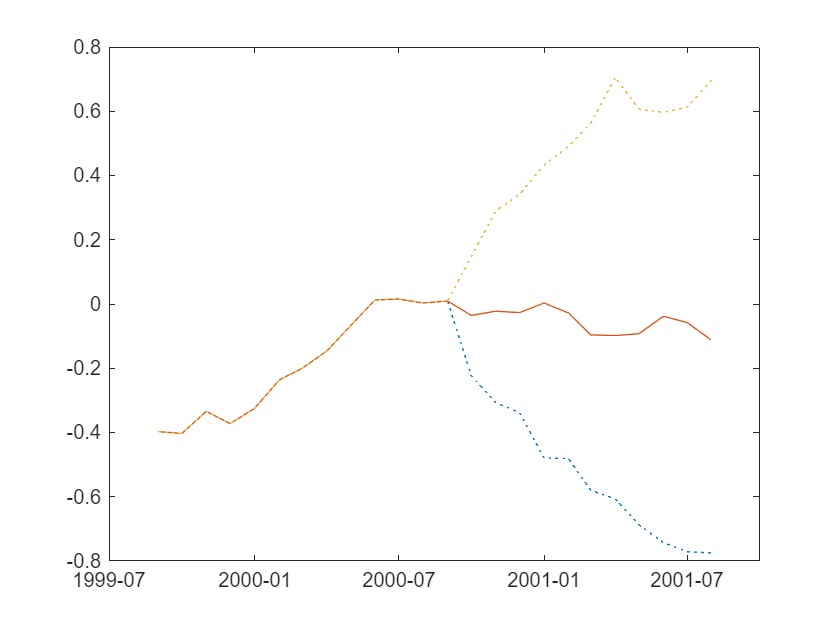


fcastTbx = modelR1.forecast(fcastSpan);
fcastPrctileTbx = tablex.apply(fcastTbx, prctileFunc);
fcastPrctileTbx = tablex.flatten(fcastPrctileTbx);

tablex.plot( ...
    fcastPrctileTbx, "FYFF", ...
    plotSettings={{"lineStyle"}, {":"; "-"; ":"}} ...
);

## Identification


identChol = identifier.Cholesky(order=[]);

modelS1 = Structural(reducedForm=modelR1, identifier=identChol);
modelS1.initialize();

info1 = modelS1.presample(numPresampled);


 Presampling from posterior (MinnesotaFAVARTwostep) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelS1.Presampled{1}

ans = struct with fields:
                  beta: [117×1 double]
                 sigma: [3×3 double]
                    FY: [511×3 double]
                    LD: [120×3 double]
    IdentificationDraw: [1×1 struct]
                     D: [3×3 double]


modelS1.Presampled{1}.IdentificationDraw

ans = struct with fields:
        A: {12×1 cell}
        C: {12×1 cell}
    Sigma: [3×3 double]


modelS1.Presampled{1}.IdentificationDraw.A{1,1}

ans =     0.6266    0.0197    0.0774
   -0.0584    0.7817    0.0941
   -0.0793    0.0449    1.0555
    0.1468    0.0445    0.0328
   -0.0062    0.0292    0.0484
    0.0044   -0.0473   -0.1471
    0.0333    0.0162    0.0133
   -0.0051    0.0799    0.0025
   -0.0033   -0.0107   -0.0374
    0.0394    0.0002    0.0201


modelS1.Presampled{1}.IdentificationDraw.A{2,1}

ans =     0.6266    0.0197    0.0774
   -0.0584    0.7817    0.0941
   -0.0793    0.0449    1.0555
    0.1468    0.0445    0.0328
   -0.0062    0.0292    0.0484
    0.0044   -0.0473   -0.1471
    0.0333    0.0162    0.0133
   -0.0051    0.0799    0.0025
   -0.0033   -0.0107   -0.0374
    0.0394    0.0002    0.0201


## **Conditional forecast**

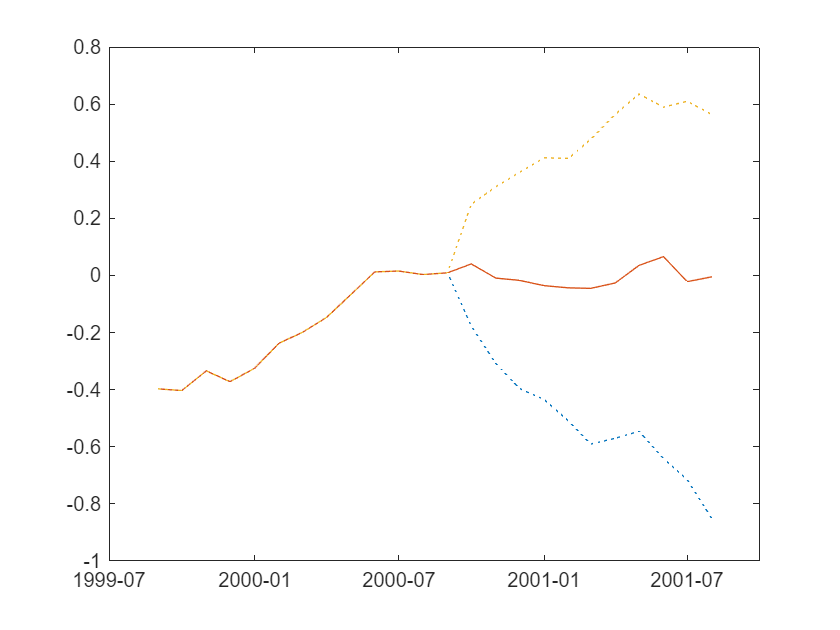


[uncFcastTbl1, uncFcastContribTbl1] = modelS1.forecast( ...
    fcastSpan, ...
    contributions=true ...
);

uncFcastPrctileTbx = tablex.apply(uncFcastTbl1, prctileFunc);
uncFcastPrctileTbx = tablex.flatten(uncFcastPrctileTbx);

tablex.plot( ...
    uncFcastPrctileTbx, "FYFF", ...
    plotSettings={{"lineStyle"}, {":"; "-"; ":"}} ...
);



condDataTbl = tablex.fromFile("condDataTblFAVAR.xlsx");
planTbl = tablex.readConditioningPlan("planTblFAVAR.xlsx");


[condFcastTbl1, condFcastContribTbl1] = modelS1.conditionalForecast( ...
    fcastSpan, ...
    conditions=condDataTbl, ...
    plan=[] ...
);


 Conditional forecast [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 




[condFcastTbl2, condFcastContribTbl2] = modelS1.conditionalForecast( ...
    fcastSpan, ...
    conditions=condDataTbl, ...
    plan=planTbl ...
);


 Conditional forecast [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 




condFcastPrctilesTbl1 = tablex.apply(condFcastTbl1, prctileFunc);
condFcastPrctilesTbl2 = tablex.apply(condFcastTbl2, prctileFunc);
